clear all;close all;clf
x = linspace(0,1e1,1e3);
n = 10;
z = 4;
nu = 1;
rho = 1e1;
% f = @(y) y./(1+y.^2).*besselj(n,y);
% f = @(y) exp(-y.*z).*besselj(nu, rho*y).*(y).^nu;

f = @(y) besselj(nu,rho*(y)).*(y).^1.*exp(2*(y));
F = f(x);
plot(x,F)
x = AllZeros(f,0,max(x));


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vect

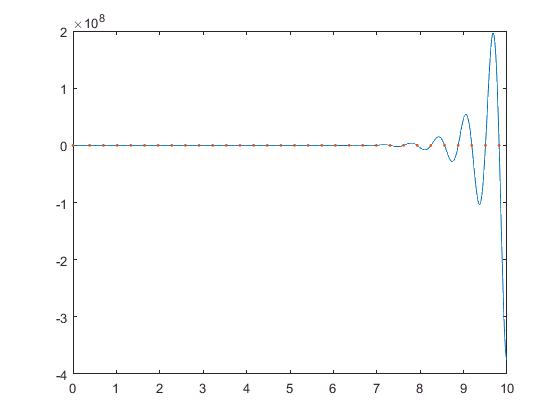

hold on
plot(x,zeros(1,length(x)),'.');
hold off

p = .011;
x = linspace(0,1e1,1e3);
f = @(y) exp(-sqrt((y).^2-1)*p)./sqrt((y).^2 -1).*(y);
F = f(x);
vpasolve(f,x)

Undefined function 'vpasolve' for input arguments of type 'function_handle'.


plot(x,F)
hold on
x = AllZeros(f,0,max(x));
plot(x,zeros(1,length(x)),'.');